
clear all; close all; clc;

% Given system matrices 
A  = [2 6; -2 -5];
C = [2 3];

% Observability matrix 
res = checkObservability(A,C);
disp(res.check);

   0



disp(res.Qo);

     2     3
    -2    -3




% Exponential of A
syms t 
eA = expm(A*t)

$$eA = \left(\begin{array}{cc} 4\,{\mathrm{e}}^{-t}-3\,{\mathrm{e}}^{-2\,t} & 6\,{\mathrm{e}}^{-t}-6\,{\mathrm{e}}^{-2\,t}\\ 2\,{\mathrm{e}}^{-2\,t}-2\,{\mathrm{e}}^{-t} & 4\,{\mathrm{e}}^{-2\,t}-3\,{\mathrm{e}}^{-t} \end{array}\right)$$

P = int(eA'*C'*C*eA, 0, inf)

$$P = \left(\begin{array}{cc} 2 & 3\\ 3 & 4.5000 \end{array}\right)$$


% x_0
f = 26*exp(-3*t);

Pi =  pinv(P);
x0 = Pi * int(eA'*C'*f, 0, inf)

$$x0 = \left(\begin{array}{c} 2\\ 3 \end{array}\right)$$


% d
temp = C*eA*x0

$$temp = 13\,{\mathrm{e}}^{-t}$$

d2 = int((f - temp)^2, 0, inf)

$$d2 = 28.1667$$

d = sqrt(d2)

$$d = 5.3072$$

clear all; 
m = 1;
% Define expectations 
syms x v u y g
y = x + u + v;
g = [];
for n = 0:m
    g = [g; y^n];
end
xl = 0; xu = 1;  % range of x
vl = 0; vu = 1;  % range of v
ul = 0; uu = 1;

EX = @(A) int(x.^A, xl, xu);
EV = @(A) int(v.^A, vl, vu);
EY = @(A) int(int(int(y.^A, x, xl, xu), v, vl, vu), ul, uu);
EXY = @(A,B) int(int(int(x.^A * y.^B, x, xl, xu), v, vl, vu), ul, uu);

% P_Hx
Rfg = EXY(1, 0:m);

A = [];
for n = 0:m
    A = [A; n:n+m];
end
Rg = EY(A)

$$Rg = \left(\begin{array}{cc} 1 & 1.5000\\ 1.5000 & 2.5000 \end{array}\right)$$

coef = Rfg * inv(Rg)

$$coef = \left(\begin{array}{cc} 0 & 0.3333 \end{array}\right)$$

coef = eval(coef)

coef =          0    0.3333


% Error d4
d4sq = EX(2) - Rfg*inv(Rg)*Rfg'

$$d4sq = 0.0556$$

d4 = sqrt(d4sq)

$$d4 = 0.2357$$

clear all;
syms x t v
fx = x*exp(-x);
EX = int(x*fx, 0, inf)

$$EX = 2$$

fv = exp(-v);
EV = int(v*fv, 0, inf)

$$EV = 1$$

clear all;
m = 1;
% Define expectations 
syms x v 
g = [];
for n = 0:m
    g = [g; y^n];
end
yl = 0; yu = inf;  % range of y
xl = 0; xu = inf; % range of x
vl = 0; vu = inf; 

y = x + v;

fx = @() x * exp(-x);
fv = @() exp(-v);
fy = @() x * exp(-x) + exp(-v);

EY = @(A) int(int(fy, x, xl, xu), vl, vu);
EX = @(A) int(x.^A*fx, xl, xu);
EV = @(A) int(v.^A*fv, vl, vu);
EXY = @(A,B) int(int(x.^A* fx * (x+v).^B * fy, x, xl, xu), vl, vu);


% P_Hx
Rfg = EXY(1, 0:m);
A = [];
for n = 0:m
    A = [A; n:n+m];
end
Rg = EY(A);

coef = Rfg * inv(Rg);
coef = eval(coef);
% Error d4
d4sq = EX(2) - Rfg*inv(Rg)*Rfg'
d4 = sqrt(d4sq);

% Plotting
t = 0:0.01:1;
% ghat
Phx = 0;
for n = 1:length(coef)
    Phx = Phx + coef(n)*t.^(n-1);
end

fig = figure("Renderer","painters",'Position',[60 60 900 650]);
    plot(t, Phx)
    grid on; grid minor; box on; hold on;
    plot(t, exp(t))
    hold off;
    title('Problem 4 Least Square Approximation - T. Koike')
    legend('$P_{\mathcal{H}}x$', '$\hat{g}$', "Location","best")
    xlabel('y')
    ylabel('g')
saveas(fig, fullfile(outdir, 'p4_lsqr_plot.png'));

t = 0:0.01:1

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


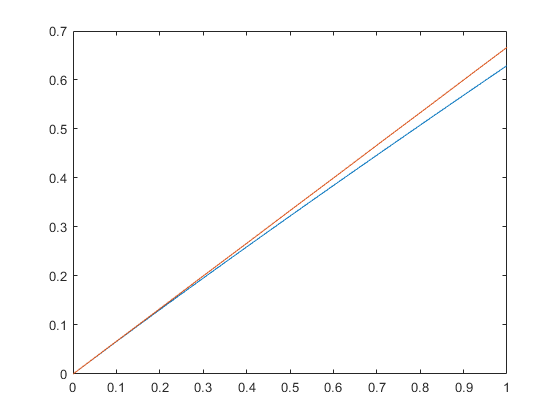


num = t.^2/2 + log(t+1) - t;
den = t - log(t+1);
gy = num ./ den;

plot(t, gy)
hold on 
plot(t, 0.6667*t)